% Double Pendulum Dynamics for use with LQR
% I_func = @(m, l) 1/12*m*l^2;
I_func = @(m, l) m*l^2; % weightless string with mass at the end
% COM_func = @(l1) l1/2;
COM_func = @(l1) l1;

syms l1 m1 b1 tau1 theta1(t)
syms l2 m2 b2 tau2 theta2(t)
syms g t

I1 = I_func(m1, l1);
I2 = I_func(m2, l2);

% % % % % LINK 1 % % % %
% COM Position of link in cartesian space
X1_COM = COM_func(l1)*sin(theta1);
Y1_COM = -COM_func(l1)*cos(theta1);

% COM Velocity of link in cartesian space
X1_COM_d = diff(X1_COM, t);
Y1_COM_d = diff(Y1_COM, t);

% COM Acceleration of link in cartesian space
X1_COM_dd = diff(X1_COM, t, 2);
Y1_COM_dd = diff(Y1_COM, t, 2);

% % % % % LINK 2 % % % %
% COM Position of link in cartesian space
X2_COM = X1_COM + COM_func(l2)*sin(theta2 + theta1);
Y2_COM = Y1_COM - COM_func(l2)*cos(theta2 + theta1);

% COM Velocity of link in cartesian space
X2_COM_d = diff(X2_COM, t);
Y2_COM_d = diff(Y2_COM, t);

% COM Acceleration of link in cartesian space
X2_COM_dd = diff(X2_COM, t, 2);
Y2_COM_dd = diff(Y2_COM, t, 2);

% Joint Velocity
theta1_d = diff(theta1, t);
theta2_d = diff(theta2, t);

% Define Kinetic Energy of System
KE1_trans = 0.5*m1*(X1_COM_d^2 + Y1_COM_d^2);
KE1_rot = 0.5*I1*theta1_d^2;
KE1 = simplify(KE1_trans + KE1_rot)

$$KE1(t) = {l_{1}}^{2}\,m_{1}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}$$


KE2_trans = 0.5*m2*(X2_COM_d^2 + Y2_COM_d^2);
KE2_rot = 0.5*I2*(theta2_d + theta1_d)^2;
KE2 = simplify(KE2_trans + KE2_rot)

$$KE2(t) = \begin{array}{l} \frac{{l_{1}}^{2}\,m_{2}\,\sigma_{1}}{2}+{l_{2}}^{2}\,m_{2}\,\sigma_{1}+{l_{2}}^{2}\,m_{2}\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}+2\,{l_{2}}^{2}\,m_{2}\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)+l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\sigma_{1}+l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2} \end{array}$$


KE = simplify(KE1 + KE2)

$$KE(t) = \begin{array}{l} {l_{1}}^{2}\,m_{1}\,\sigma_{1}+\frac{{l_{1}}^{2}\,m_{2}\,\sigma_{1}}{2}+{l_{2}}^{2}\,m_{2}\,\sigma_{1}+{l_{2}}^{2}\,m_{2}\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}+2\,{l_{2}}^{2}\,m_{2}\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)+l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\sigma_{1}+l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2} \end{array}$$


% Define Potential Energy of System
% gravity
PE1 = m1 * (Y1_COM + l1) * g;
PE2 = m2 * (Y2_COM + (l1+l2)) * g;
PE = PE1 + PE2;

% Define Lagrangian
L =simplify( KE - PE)

$$L(t) = \begin{array}{l} {l_{1}}^{2}\,m_{1}\,\sigma_{1}-g\,l_{1}\,m_{2}-g\,l_{2}\,m_{2}-g\,l_{1}\,m_{1}+\frac{{l_{1}}^{2}\,m_{2}\,\sigma_{1}}{2}+{l_{2}}^{2}\,m_{2}\,\sigma_{1}+{l_{2}}^{2}\,m_{2}\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}+2\,{l_{2}}^{2}\,m_{2}\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)+g\,l_{2}\,m_{2}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)+g\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+g\,l_{1}\,m_{2}\,\cos\left(\theta_{1}\left(t\right)\right)+l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\sigma_{1}+l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2} \end{array}$$


% take derivative
% do this for each joint
syms th1 th1_d th1_dd
syms th2 th2_d th2_dd
orig_list = [theta1, diff(theta1, t), diff(theta1, t, 2), ...
    theta2, diff(theta2, t), diff(theta2, t, 2)];
manip_list = [th1, th1_d, th1_dd...
    th2, th2_d, th2_dd];
L_sub = subs(L, orig_list, manip_list)

$$L\_sub(t) = {l_{1}}^{2}\,m_{1}\,{{\mathrm{th}}_{1,d}}^{2}+\frac{{l_{1}}^{2}\,m_{2}\,{{\mathrm{th}}_{1,d}}^{2}}{2}+{l_{2}}^{2}\,m_{2}\,{{\mathrm{th}}_{1,d}}^{2}+{l_{2}}^{2}\,m_{2}\,{{\mathrm{th}}_{2,d}}^{2}-g\,l_{1}\,m_{1}-g\,l_{1}\,m_{2}-g\,l_{2}\,m_{2}+g\,l_{2}\,m_{2}\,\cos\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)+g\,l_{1}\,m_{1}\,\cos\left({\mathrm{th}}_{1}\right)+g\,l_{1}\,m_{2}\,\cos\left({\mathrm{th}}_{1}\right)+2\,{l_{2}}^{2}\,m_{2}\,{\mathrm{th}}_{1,d}\,{\mathrm{th}}_{2,d}+l_{1}\,l_{2}\,m_{2}\,{{\mathrm{th}}_{1,d}}^{2}\,\cos\left({\mathrm{th}}_{2}\right)+l_{1}\,l_{2}\,m_{2}\,{\mathrm{th}}_{1,d}\,{\mathrm{th}}_{2,d}\,\cos\left({\mathrm{th}}_{2}\right)$$

% annoying!: can't use jacobian here because can't access individual equations later on
% or maybe you can?
dl_dqd_sub = jacobian(L_sub, [th1_d, th2_d]);
dl_dqd = subs(dl_dqd_sub, manip_list, orig_list);
d_dt_dl_dqd = diff(dl_dqd, t);
d_dt_dl_dqd_sub = subs(d_dt_dl_dqd, orig_list, manip_list);
dl_dq_sub = jacobian(L_sub, [th1, th2]);
eq_sub = d_dt_dl_dqd_sub - dl_dq_sub

$$eq\_sub(t) = \begin{array}{l} \left(\begin{array}{cc} 2\,{l_{1}}^{2}\,m_{1}\,{\mathrm{th}}_{1,\mathrm{dd}}+{l_{1}}^{2}\,m_{2}\,{\mathrm{th}}_{1,\mathrm{dd}}+\sigma_{3}+\sigma_{2}+\sigma_{1}+g\,l_{1}\,m_{1}\,\sin\left({\mathrm{th}}_{1}\right)+g\,l_{1}\,m_{2}\,\sin\left({\mathrm{th}}_{1}\right)-l_{1}\,l_{2}\,m_{2}\,{{\mathrm{th}}_{2,d}}^{2}\,\sin\left({\mathrm{th}}_{2}\right)+2\,l_{1}\,l_{2}\,m_{2}\,{\mathrm{th}}_{1,\mathrm{dd}}\,\cos\left({\mathrm{th}}_{2}\right)+l_{1}\,l_{2}\,m_{2}\,{\mathrm{th}}_{2,\mathrm{dd}}\,\cos\left({\mathrm{th}}_{2}\right)-2\,l_{1}\,l_{2}\,m_{2}\,{\mathrm{th}}_{1,d}\,{\mathrm{th}}_{2,d}\,\sin\left({\mathrm{th}}_{2}\right) & \sigma_{3}+\sigma_{2}+\sigma_{1}+l_{1}\,l_{2}\,m_{2}\,{{\mathrm{th}}_{1,d}}^{2}\,\sin\left({\mathrm{th}}_{2}\right)+l_{1}\,l_{2}\,m_{2}\,{\mathrm{th}}_{1,\mathrm{dd}}\,\cos\left({\mathrm{th}}_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=g\,l_{2}\,m_{2}\,\sin\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)\\ \sigma_{2}=2\,{l_{2}}^{2}\,m_{2}\,{\mathrm{th}}_{2,\mathrm{dd}}\\ \sigma_{3}=2\,{l_{2}}^{2}\,m_{2}\,{\mathrm{th}}_{1,\mathrm{dd}} \end{array}$$

eq = subs(eq_sub, manip_list, orig_list)

$$eq(t) = \begin{array}{l} \left(\begin{array}{cc} 2\,{l_{1}}^{2}\,m_{1}\,\sigma_{5}+{l_{1}}^{2}\,m_{2}\,\sigma_{5}+\sigma_{3}+\sigma_{2}+\sigma_{1}+g\,l_{1}\,m_{1}\,\sin\left(\theta_{1}\left(t\right)\right)+g\,l_{1}\,m_{2}\,\sin\left(\theta_{1}\left(t\right)\right)-l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}+2\,l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\sigma_{5}+l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\sigma_{4}-l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\,2 & \sigma_{3}+\sigma_{2}+\sigma_{1}+l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=g\,l_{2}\,m_{2}\,\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\\ \sigma_{2}=2\,{l_{2}}^{2}\,m_{2}\,\sigma_{4}\\ \sigma_{3}=2\,{l_{2}}^{2}\,m_{2}\,\sigma_{5}\\ \sigma_{4}=\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)\\ \sigma_{5}=\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right) \end{array}$$


% dl_dq1d_sub = diff(L_sub, th1_d)
% dl_dq2d_sub = diff(L_sub, th2_d)
% dl_dq1d = subs(dl_dq1d_sub, manip_list, orig_list)
% dl_dq2d = subs(dl_dq2d_sub, manip_list, orig_list)
% d_dt_dl_dqd_sub = subs(d_dt_dl_dqd, orig_list, manip_list)



% add generalized forces
syms Q1 Q2
LHS_1 = Q1-b1*diff(theta1,t);
LHS_2 = Q2-b2*diff(theta2,t);
% eq_sub_temp = eq_sub(t)
% eq1_sub = eq_sub_temp(1);
% eq2_sub = eq_sub_temp(2);
% eq1 = subs(eq1_sub, manip_list, orig_list)
EOM = eq == [LHS_1, LHS_2];

% solve for theta_dd
EOM_sub = subs(EOM, orig_list, manip_list);
S = solve(EOM_sub, [th1_dd, th2_dd]);
% simplify(S.th1_dd)
% simplify(S.th2_dd)
% Actual equations of motion
matlabFunction([S.th1_dd, S.th2_dd], 'File', 'DoublePendulum_Dynamics');

% linearize so I can use LQR -- only valid around stationary points
df_dq_th1 = jacobian(S.th1_dd, [th1, th1_d, th2, th2_d]);
df_dq_th2 = jacobian(S.th2_dd, [th1, th1_d, th2, th2_d]);
df_du_th1 = jacobian(S.th1_dd, [Q1, Q2]);
df_du_th2 = jacobian(S.th2_dd, [Q1, Q2]);

A = [0, 1, 0, 0;
    df_dq_th1;
    0, 0, 0, 1;
    df_dq_th2];
B = [0, 0;
    df_du_th1;
    0, 0;
    df_du_th2];
matlabFunction(A, 'File', 'A_linearized');
matlabFunction(B, 'File', 'B_linearized');
% % cool but totally wrong!
% % seperate out control part of equation
% sep_th1_dd = children(collect(S.th1_dd, [Q1, Q2, th1, th1_d, th1_dd, th2, th2_d, th2_dd]));
% rem_th1_dd = sum(sep_th1_dd(3:end));
% sep_th1_dd_Q1 = children(sep_th1_dd(1));
% sep_th1_dd_Q2 = children(sep_th1_dd(2));
% temp_th1_Q1 = children(sep_th1_dd_Q1(1));
% temp_th1_Q2 = children(sep_th1_dd_Q2(1));
% 
% sep_th2_dd = children(collect(S.th2_dd, [Q1, Q2, th1, th1_d, th1_dd, th2, th2_d, th2_dd]));
% rem_th2_dd = sum(sep_th2_dd(3:end));
% sep_th2_dd_Q1 = children(sep_th2_dd(1));
% sep_th2_dd_Q2 = children(sep_th2_dd(2));
% temp_th2_Q1 = children(sep_th2_dd_Q1);
% temp_th2_Q2 = children(sep_th2_dd_Q2);
% 
% 
% % g = [temp_th1_Q1(1), temp_th1_Q2(1);
% %     temp_th2_Q1(1), temp_th2_Q2(1)];
% 
% 
% g = [sep_th1_dd_Q1(1), sep_th1_dd_Q2(1);
%     sep_th2_dd_Q1(1), sep_th2_dd_Q2(1)];
% 
% % seperate out state stuff part of stuff
% states = [th1, th1_d, th2, th2_d];
% syms f f_temp
% for j = 1:2
%     if j == 1
%         sep = sep_th1_dd;
%     elseif j == 2
%         sep = sep_th2_dd;
%     end
%     
%     for i1 = 1:length(states)
%         f_temp = sym('0'); 
%         for i_term = 3:length(sep)
%             temp = children(sep(i_term));
%             if length(temp) == 2 % check for multiple terms
%                 if has(temp(2), states(i1)) % check if the desired variable is there
%                     if length(children(temp(2))) < 2 % check if it is a power
%                         f_temp = f_temp + temp(1);
%                     end
%                 end
%             end
%         end
%         f(j,i1) = f_temp;
%     end
%     
% end




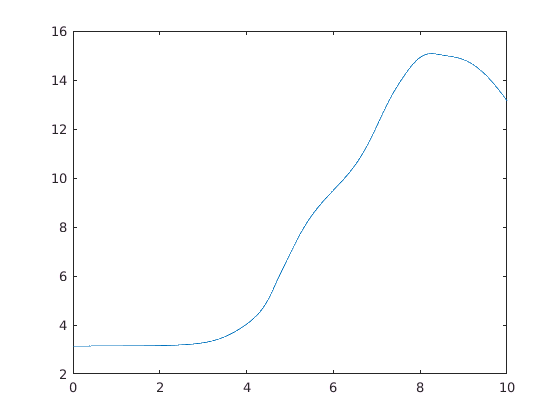

tspan = 0:.01:10;
y0 = [pi+.001;0;0;0];
[t_sim,y] = ode45(@(t,y)DoublePendulum_Dynamics_ODE(0,0,0.1,0.1,9.8,2,1,1,1,y),tspan,y0);
plot(t_sim,y(:,1))